# Laboratorio 2 

## Robótica 2021 - 1 

### Luis Alberto Chavez Castro

### Jorge Luis Reina Jara

### Edwin Alexander Casallas Moreno

##  Modelo cinemático inverso *fanuc LR Mate 200 ib*

### **Parte I, Robot y Ruta.**

El robot asignado para el desarrolllo de este laboratorio fue el modelo* fanuc LR Mate 200 ib, Se asigna un modelo de robot industrial a cada equipo de trabajo y un plano en el que debe crear una ruta y simular el movimiento de seguimiento del robot. Deberá presentar al menos la simulación de esa ruta, pueden crear y simular otras rutas y/o otros planos..*

### Localización de ruta.

Plano - Vector, significa que la ruta que el robot va a simular debe estar en un plano normal al vector indicado en la tabla.

La ruta debe tener una de las dos formas mostradas en la figura 2. Cada grupo selecciona la que deseen.

La dimensión L debe ser aproximadamente 0,4 del alcance horizontal máximo del robot.

El grupo decide la posición de la ruta en el espacio cartesiano de manera que quede dentro del espacio diestro del robot.

la ruta seleccionada por el equipo de trabajo es la que se muestra a continuación:

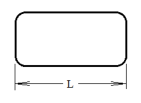

### Características y modelo del robot

Busque información t´ ecnica del robot, obtenga catálogos de fabricante, presente en el informe:

#### 1. Imagen del robot.

el Robot a modelar es el modelo LR Mate 200iB de Fanuc, que se muestra en el modelo siguiente y se muestra en una fotografia en la siguiente imagen:

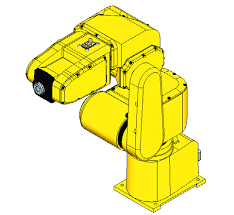

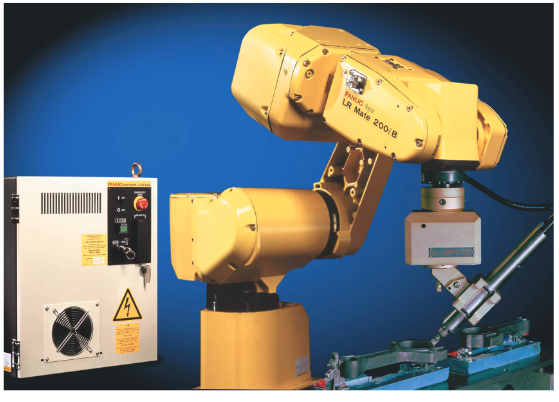

#### 2. Capacidad de carga.

El  Robot multiusos de productividad elevada FANUC LR Mate 200iB posee una capacidad de carga de 7Kg basados en el Datasheet aunque la mayoria de distribuidores solo hacian promocion de una capacidad de carga de maximo 5kg.

#### 3. Alcance vertical y horizontal.

El  Robot multiusos de productividad elevada FANUC LR Mate 200iB hace parte de la gama de mini robots que buscan emular las longitudes de un brazo humano.

En su punto máximo suerior logra 970mm en altura, medidos desde la base de instalacion del robot, hacia el frente logra su extension de 770mm desde su origen.

#### 4. Repetibilidad.

La repetiiblidad de este robot esta el rango de las centecimas de milimetro, segun el fabricante es de +/-0.04 mm.

#### 5. Gráfica(s) de espacio alcanzable.

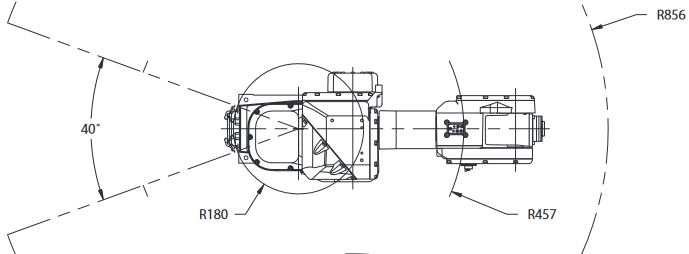

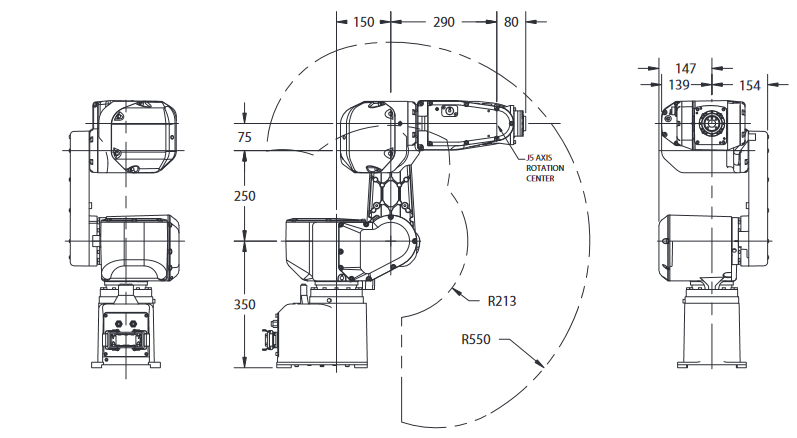

#### 6. Tabla de parámetros DH.

# 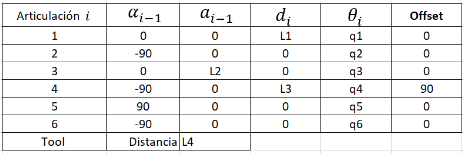

#### 7. Qué software utiliza el fabricante para diseño de celdas o programación.

el Fabricante Fanuc, emplea su propio software llamado  ROBOTSE SOFTWARE y para este robot el controlador  estándar de Fanuc  R-30iB Plus  es el que mejor se adapta a las necesidades de control de este modelo en especifico.

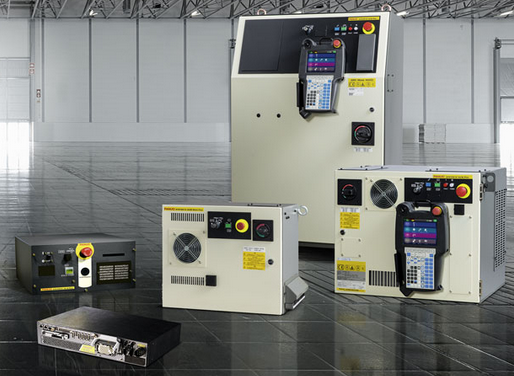

por otra parte se el mando a distancia en esta familia de robots se conoce como i-pendant y se muestra a continuacion:

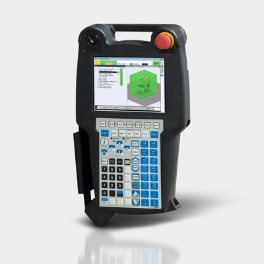

### Modelos

#### Peter Corke


%% Robot RPRRR 5 gdl
clf
clc
L1 =0.707;
W = [-60 90 -60 60 -80 40]*10; %Volumen a graficar

 plot_options = {'workspace',W,'scale', 0.8,'view',[125 25], 'tilesize',2,  'ortho', 'lightpos',[700 700 1000] };

%            Theta  d   a   alpha  type mdh offset  qlim
syms l1 l2 l3 l4 q6

l1=150;
l2=250;
l3=75;
l4=290;
q6=pi/2;
L(1)=Link([0 l1 0 0 0 0],'modified'); 
L(2)=Link([0 0 0 -pi/2 0 0],'modified');
L(3)=Link([0 0 l2 0 0 0],'modified');
L(4)=Link([0 0 0 -pi/2 0 pi/2],'modified'); %Poner el offset arriba
L(5)=Link([0 l3 0 pi/2 0 0],'modified'); %Revisar el menos en la tabla
L(6)=Link([0 0 0 -pi/2 0 0],'modified');
Robot_Fanuc = SerialLink(L,'name','Fanuc LR mate 200iB','plotopt',plot_options)

 
Robot_Fanuc = 
 
Fanuc LR mate 200iB (6 axis, RRRRRR, modDH, fastRNE)             
                                                                 
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|        150|          0|          0|          0|
|  2|         q2|          0|          0|     -1.571|          0|
|  3|         q3|          0|        250|          0|          0|
|  4|         q4|          0|          0|     -1.571|      1.571|
|  5|         q5|         75|          0|      1.571|          0|
|  6|         q6|          0|          0|     -1.571|          0|
+---+-----------+-----------+-----------+-----------+-----------+
                                                                 
grav =    0  base = 1  0  0  0   tool =  1  0  0  0              
          0         0  1  0  0           0  1  0  0      

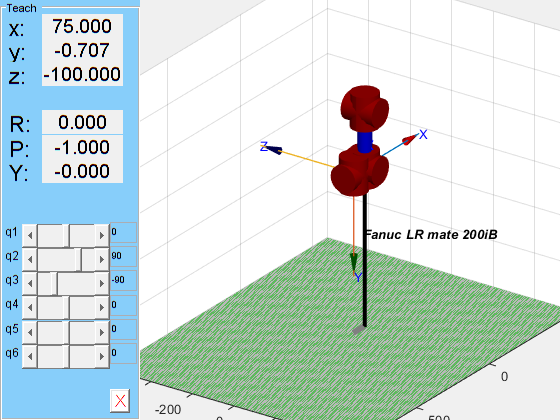

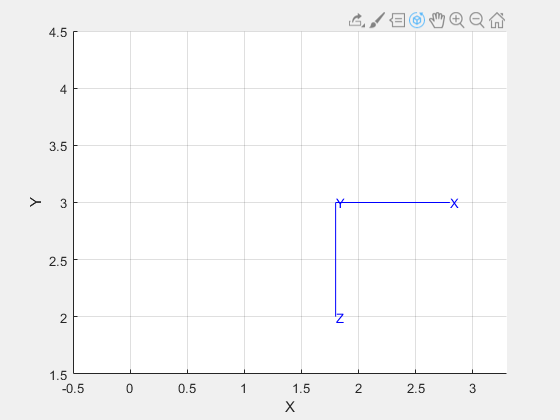


%Robot_Fanuc.plot((0 pi/2 -pi/2 0 0 0))
%%
Robot_Fanuc.tool = [ 0  0   1  L1;... %ubicacion herramienta
               1  0   0  0 ;...
               0  1   0  0 ;...
               0  0   0  1  ];

%%

q = [0 pi/2 -pi/2 0 0 0]; %posicion Home
%q = [0 0 0 0 0 0]; %posicion Home

Robot_Fanuc.teach(q) %se almacena una posicion especifica como HOME

hold on
trplot(eye(4),'length',2 )

%% cinematica inversa por el metodo de geometrico directo
TCP = Robot_Fanuc.fkine(q)  % ikine

TCP =    -1.0000         0    0.0000   75.0000
   -0.0000    0.0000   -1.0000   -0.7070
   -0.0000   -1.0000   -0.0000 -100.0000
         0         0         0    1.0000


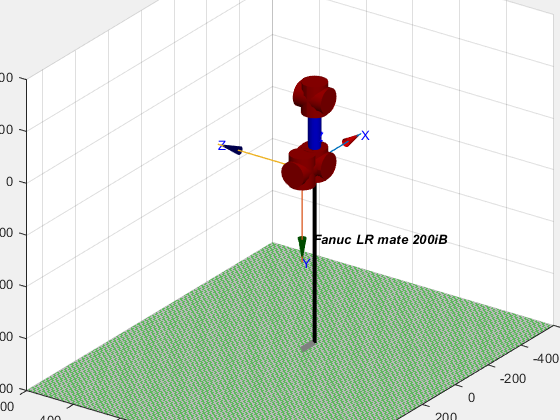

trplot(TCP,'length',2 )

tr2rpy(TCP,'zyx','deg')

ans =  -180.0000    0.0000  -90.0000



%% para las trayectorias se emplea:
T0=transl( 1.0, 3, 1) * trotx(pi/2);
T1=transl(1.8, 3, 1) * trotx(pi/2);
T = ctraj(T0, T1, 50);
T(:,:,1) %primera pose

ans =     1.0000         0         0    1.0000
         0    0.0000   -1.0000    3.0000
         0    1.0000    0.0000    1.0000
         0         0         0    1.0000


T(:,:,10) %decima pose

ans =     1.0000         0         0    1.0607
         0    0.0000   -1.0000    3.0000
         0    1.0000    0.0000    1.0000
         0         0         0    1.0000


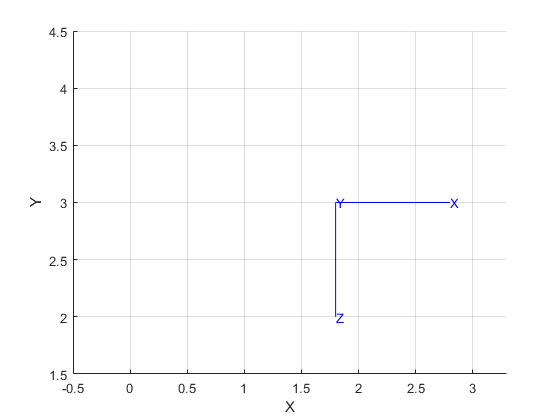

clf; tranimate(T)

### Robotics Systems Toolbox (RST) de MATLAB®

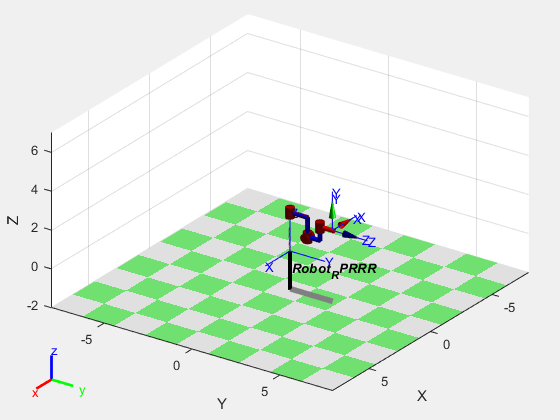

Robot_Fanuc = loadrobot("kinovaGen3",'DataFormat','row','Gravity',[0 0 -9.81]); %importacion del robot
ActualRobotJConfig = homeConfiguration(Robot_Fanuc); %definicion del Home segun el RObot Importado
numJoints = numel(ActualRobotJConfig); %numero de Juntas
endEffector = "EndEffector_Link";      %
show(Robot_Fanuc);

timeStep = 0.1;                        % tiempo de desplazamiento en segundos
toolSpeed = 0.1;                       % Velocidad de la herramienta en m/s 
jointInit = ActualRobotJConfig;        %configuracion inicial del efector final
taskInit = getTransform(Robot_Fanuc,jointInit,endEffector); %inicio de la tarea de movimiento

taskFinal = trvec2tform([0.4,0,0.6])*axang2tform([0 1 0 pi]); %coordenadas finales de la tarea




robot = loadrobot('fanucLRMate200ib');

Error using loadrobot (line 46)
Expected robotName to match one of these values:

'abbIrb120', 'abbIrb120T', 'kinovaGen3', 'kinovaJacoJ2N6S200', 'kinovaJacoJ2N6S300', 'kinovaJacoJ2N7S300', 'kinovaJacoJ2S6S300', 'kinovaJacoJ2S7S300', 'kinovaJacoTwoArmExample', 'kinovaMicoM1N4S200', 'kinovaMicoM1N6S200', 'kinovaMicoM1N6S300', 'rethinkBaxter', 'willowgaragePR2'

The input, 'fanucLRMate200ib', did not match any of the valid values.



show(robot);

PARTE 3

JACOBIANO